# Ex 6


$$c_n(f) = \frac{1}{2\pi} \int_{-\pi}^{\pi} cos(\alpha x) e^{-inx} dx$$



$$=\frac{1}{4\pi} \int_{-\pi}^{\pi} e^{i\alpha x - inx}+e^{-i\alpha x - inx} dx$$



$$=\frac{1}{4i\pi} [\frac{e^{ix(\alpha-n)}}{\alpha-n}+\frac{e^{ix(-\alpha-n)}}{(-\alpha-n)}]_{-\pi}^{\pi}$$



$$=\frac{1}{2\pi}[\frac{sin(\alpha-n)\pi}{\alpha-n}+\frac{sin(\alpha+n)\pi}{\alpha + n}]$$



$$=\frac{(-1)^n sin\alpha \pi}{2\pi} (\frac{1}{\alpha-n}+\frac{1}{\alpha+n}) = \frac{(-1)^n sin\alpha \pi}{2\pi} \frac{2\alpha}{\alpha^2-n^2}$$


Dirichlet theorem:


$$\forall x \in [-\pi,\pi] \ cos(\alpha x) = \frac{sin\alpha\pi}{2\pi} \sum_{n\in Z} (-1)^n\frac{2\alpha}{\alpha^2-n^2} e^{inx}$$


Take $x=0, \alpha\pi=t$


$$\frac{1}{\sin(t)} = \frac{1}{2}\sum_{n\in Z} \frac{(-1)^n 2t}{t^2-n^2\pi^2}$$



$$=\frac{1}{t} + \sum_{n=1}^{\infty} \frac{(-1)^n 2t}{t^2-n^2\pi^2}$$


Then take $x=\pi, \alpha \pi = t$


$$\cos(t) = \frac{\sin t}{2} \sum_{n\in Z}(-1)^n \frac{2t}{t^2-n^2\pi^2}e^{in\pi}$$



$$sincd_N(x) = \sum_{k \in Z} sinc(x-kN)\\
=\sum_{k \in Z} \frac{sin(\pi x - \pi kN)}{\pi (x-kN)}$$



$$\frac{\pi sincd_N(x)}{\sin \pi x} = \sum_{k \in Z} (-1)^{kN} \frac{1}{x-kN}$$



$$= \frac{1}{x} + \sum_{k=1}^{\infty} (-1)^{kN} (\frac{1}{x-kN}+\frac{1}{x+kN})$$


Take $t=\frac{\pi x}{N}$


$$=\frac{\pi}{N}(\frac{1}{t} + \sum_{k\geq 1} \frac{(-1)^{kN}2t}{t^2-k^2\pi^2})$$


# Ex 7

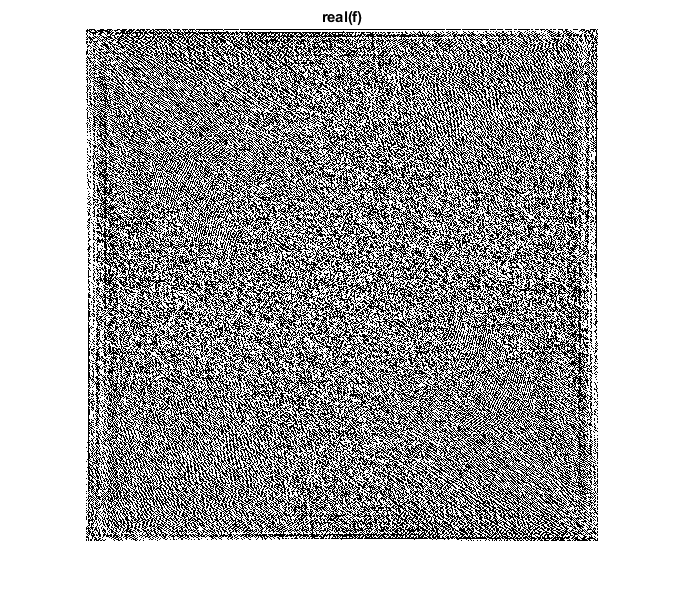

u = double(imread('lena.pgm'));
f = fft2(u);

imshow(real(f)); % even function, many values are saturated
title('real(f)');

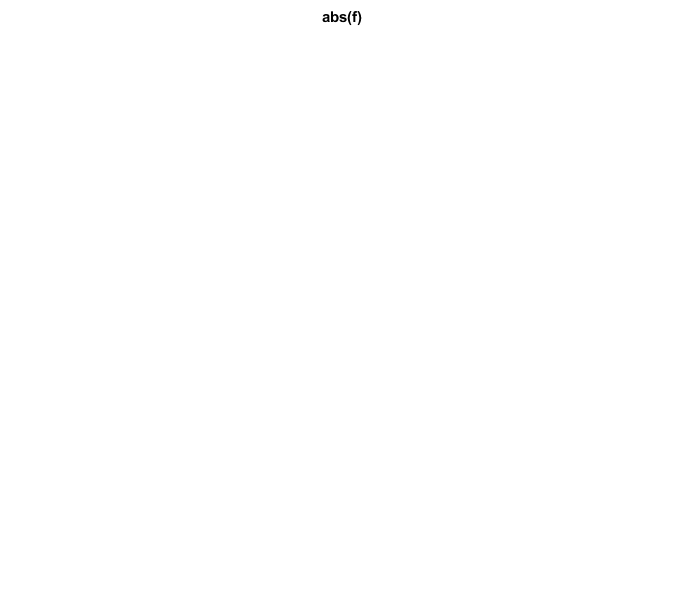


imshow(abs(f)); % all values are saturated
title('abs(f)');

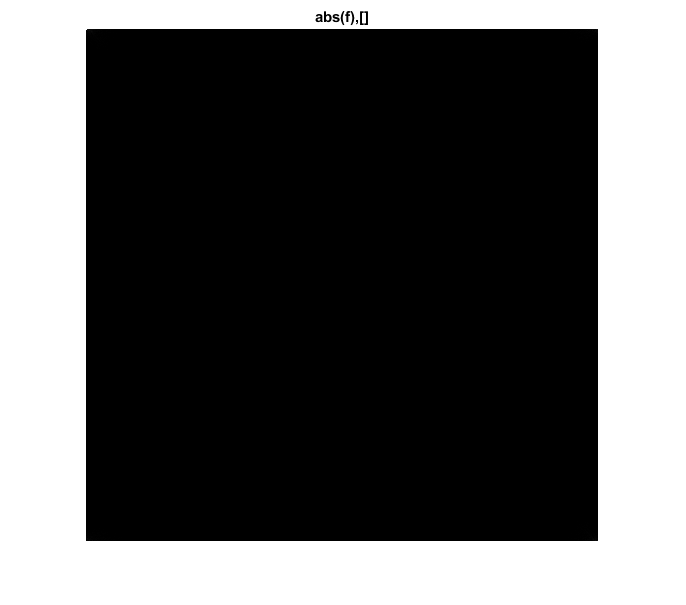


imshow(abs(f),[]); 
title('abs(f),[]'); 

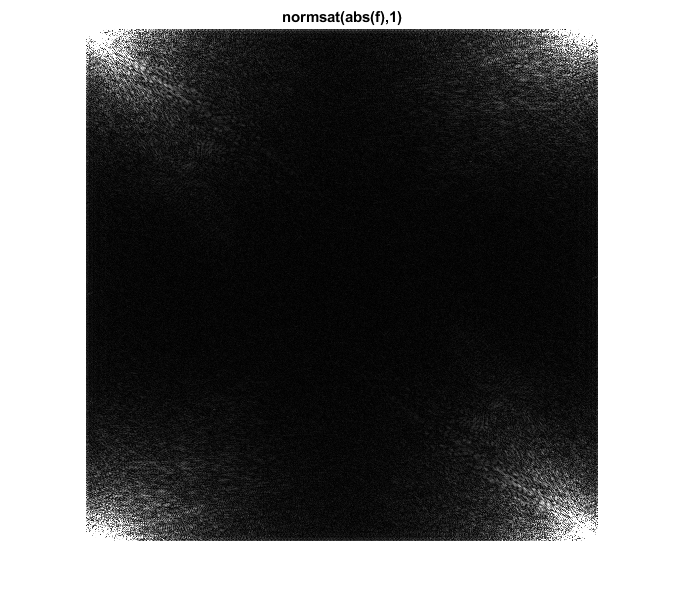

% only top-left value is visible
% which is too high compared to other values

imshow(normsat(abs(f),1)); 
title('normsat(abs(f),1)'); 

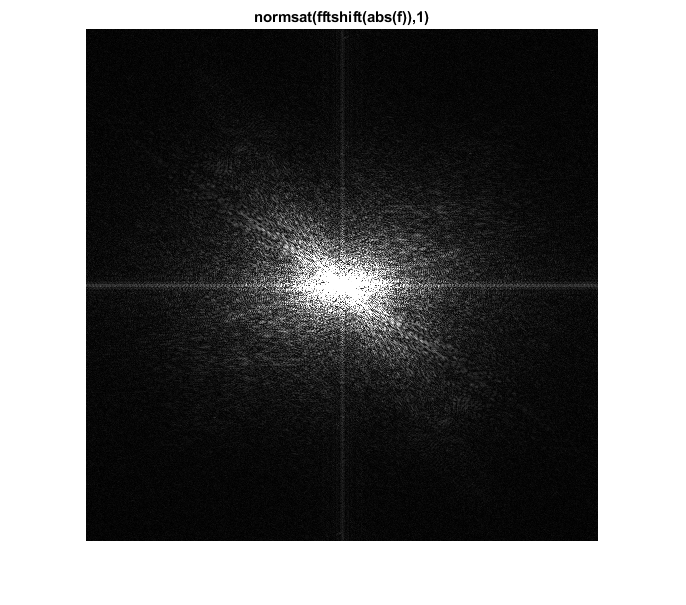

% one percent of total range is shown
% we see low-frequency entries (near corner) have larger values

imshow(normsat(fftshift(abs(f)),1));
title('normsat(fftshift(abs(f)),1)');

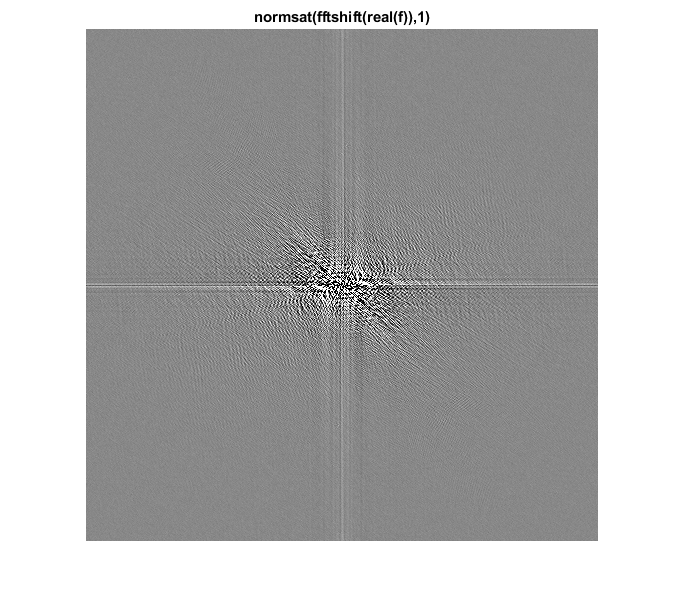

% when shifted, low-frequency entries are centered, 
% high-frequency entries are near corner

imshow(normsat(fftshift(real(f)),1));
title('normsat(fftshift(real(f)),1)');

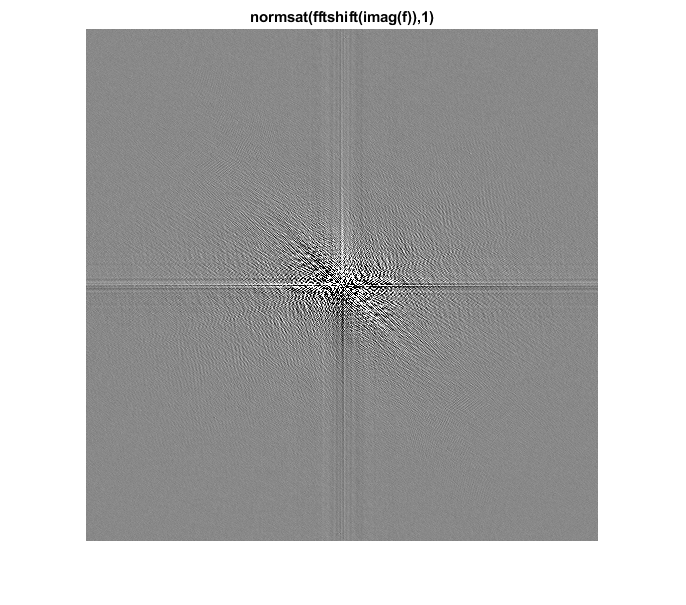

% real part of f is even because image is real valued

imshow(normsat(fftshift(imag(f)),1));
title('normsat(fftshift(imag(f)),1)');

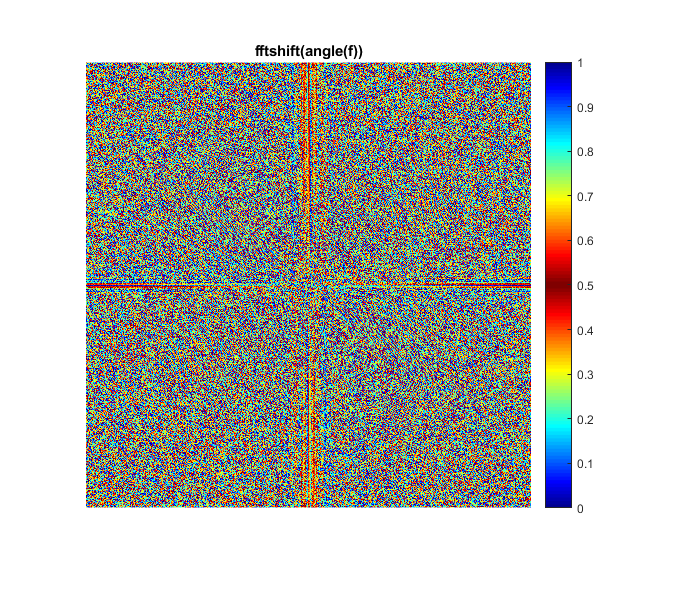

% imaginary part of f is odd because image is real valued

jet_wrap = vertcat(jet,flipud(jet));
imshow(mat2gray(fftshift(angle(f))));
colormap(gca,jet_wrap);
colorbar;
title('fftshift(angle(f))');

% angle plotted by a circular colormap


# Ex 8